# Create Onramp and Terrain-Aware Global Planners for Offroad Navigation

This example shows how to develop an onramp planner to find the shortest path to get on the road network from a location off of the road network. The example then shows you how to create a terrain-aware planner that you can use in regions of the map that lack structure, or as a fallback planner in the event that the path-following controller fails to find a local solution. This example builds on the [Create Route Planner for Offroad Navigation Using Digital Elevation Data](http://./CreateRoutePlannerUsingDigitalElevationData.mlx) example, in which you develop a graph-based planner to plan routes through a road network derived from the offroad elevation data of a copper mine. 

## Set Up Road Network Path Planner

### Load Terrain and Path Data

Load a MAT file containing data generated from the Create Route Planner for Offroad Navigation Using Digital Elevation Data example into the workspace.

load("OpenPitMinePart1Data.mat","imSlope","pathList","dem")

Currently, the data consists of grid indices from image analysis representing paths. To align these paths with practical geographic coordinates, convert the grid indices into local *xy*-coordinates using an occupancy map that incorporates the slope data of the terrain.

res = 1;
binMap = binaryOccupancyMap(~imSlope,res);

localPathList = pathList;
for i = 1:numel(pathList)
    localPathList(i).Path = grid2local(binMap,pathList(i).Path);
end

### Create A* Path Planner

First, you must create a global planner for planning in the road network.  This serves as a high-level planner that generates precomputed routes through the mine. 

Convert the *xy*-coordinate path list into data for a `navGraph` object. Set the maximum edge length to 50. In this example, setting the maximum edge length to 50 improves the likelihood of finding a collision-free path between any start and goal poses while keeping the graph relatively sparse.

maxElementPerEdge = 50;
[nodes,edges,edge2pathIdx,cachedPaths] = exampleHelperPath2GraphData(localPathList,maxElementPerEdge);

Use the `exampleHelperDefaultEdgeCost` helper function to compute the edge costs and create the state and link tables. In this example, the default edge costs are the accumulated *xy*-distance along the paths.

edgeCosts = exampleHelperDefaultEdgeCost(cachedPaths,edge2pathIdx);
stateTable = table(nodes,VariableNames="StateVector");
linkTable = table(edges,edgeCosts,edge2pathIdx(:),VariableNames=["EndStates","Weight","Edge2PathIdx"]);

Create the road network as a `navGraph` object, and use the graph to create the A* path planner as a [`plannerAStar`](https://www.mathworks.com/help/nav/ref/plannerastar.html) object.

roadNetwork = navGraph(stateTable,linkTable);
routePlanner = plannerAStar(roadNetwork);

### Plan Network Path

Next, plan a network path through the road network, with start and goal poses outside the road network. Note that these poses contain orientation, even though the graph considers only the *xy*-plane, because orientation is relevant for planning paths that consider the kinematic constraints of the haul truck.

start = [327 425 pi/8];
goal  = [792 430 pi];

Find the relative positions of each node in the start and goal locations. Then find the nodes with the shortest distance to the start and goal locations.

relPosStart = nodes(:,1:2)-start(1:2);
relPosGoal = nodes(:,1:2)-goal(1:2);
[dStart,nearStartIdx] = min(vecnorm(relPosStart,2,2));
[dGoal,nearGoalIdx] = min(vecnorm(relPosGoal,2,2));

Plan a path on the road network.

[waypoints,solnInfo] = plan(routePlanner,nearStartIdx,nearGoalIdx);

Reconstruct the full path by converting the planned path into a link sequence, and use that link sequence to get the full path from the cached paths.

edgePairs = [solnInfo.PathStateIDs(1:end-1)' solnInfo.PathStateIDs(2:end)'];
linkID = findlink(routePlanner.Graph,edgePairs);
networkPath = vertcat(cachedPaths(routePlanner.Graph.Links.Edge2PathIdx(linkID)).Path);

Downstream controllers typically perform better with smooth reference paths, especially if the vehicle is subject to non-holonomic constraints. You can smooth a path through various methods, such as curve fitting or interpolation. 

Smooth the path using the [`exampleHelperSmoothReferencePath`](matlab:open('exampleHelperSmoothReferencePath')) helper function. The function improves the smoothness of the path by first subsampling the initial path, then applying a piecewise continuous cubic polynomial fit to the subsampled points before resampling both the path and its orientation. Increasing the interval for subsampling can result in a smoother path, but might also cause a larger deviation from the original path.

subsampleInterval = 5;
smoothedNetworkPath = exampleHelperSmoothReferencePath(networkPath,subsampleInterval);

### Visualize Road Network and Network Path

Show the pit mine occupancy map, and then overlay the network graph.

hIm = show(binMap);
hold on
gHandle = show(routePlanner.Graph); 
gHandle.XData = routePlanner.Graph.States.StateVector(:,1); 
gHandle.YData = routePlanner.Graph.States.StateVector(:,2);

Plot the planned network path, the smoothed network path, and the start and goal poses.

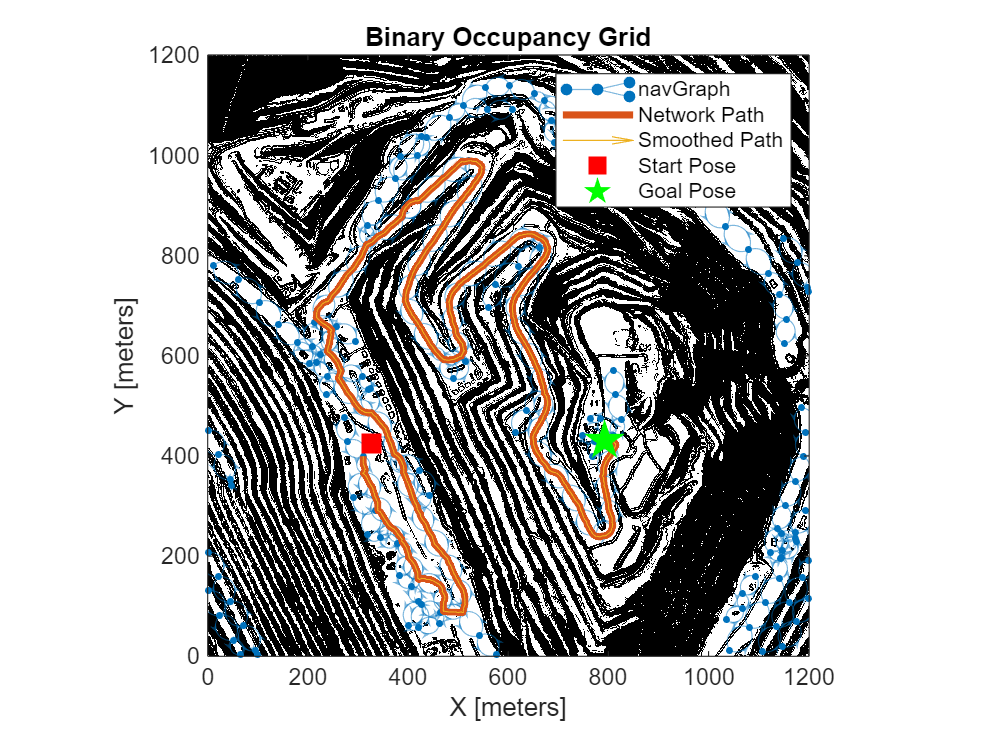

exampleHelperPlotLines(networkPath,{'LineWidth',3});
exampleHelperPose2Quiver(smoothedNetworkPath,{'AutoScale','off'});
startSpec = plannerLineSpec.start(MarkerEdgeColor="red",MarkerFaceColor="red");
goalSpec = plannerLineSpec.goal(MarkerEdgeColor="green",MarkerFaceColor="green");
plot(start(1),start(2),startSpec{:})
plot(goal(1),goal(2),goalSpec{:})
legendStrings = ["navGraph","Network Path","Smoothed Path","Start Pose","Goal Pose"];
legend(legendStrings)
hold off

## Create Onramp Planner to Merge onto Network Path

The network path you planned represents the shortest path between the nearest nodes on the road network to the start and goal positions, but this path does not extend directly to the specified starting pose because your specified starting pose lies outside the road network. To address this, create an onramp planner to plan a path from the starting pose to the start node, or an unobstructed node, of the network path.

To enable the onramp planner to more successfully find a path onto the network path, find the edges that are connected to the start node. In the case that the onramp planner cannot find a path to the start node, it might be more successful connecting to a nearby edge. 

First, look up all the nodes that are connected to the start node by using the [`successors`](https://www.mathworks.com/help/nav/ref/navgraph.successors.html) object function of the network graph.

successorNodeIDs = successors(routePlanner.Graph,solnInfo.PathStateIDs(1));

Next, use the [`findlink`](https://www.mathworks.com/help/nav/ref/navgraph.findlink.html) object function of the network graph to retrieve the IDs of the links connecting the start node to its successors.

initLinkNodePair = [repmat(solnInfo.PathStateIDs(1),numel(successorNodeIDs),1) successorNodeIDs(:)];
initLinkID = findlink(routePlanner.Graph,initLinkNodePair);

Get the edge paths connected to the start node.

initEdgePaths = cachedPaths(routePlanner.Graph.Links.Edge2PathIdx(initLinkID));

Plot the network path and starting pose. Then, center the axes around the starting pose.

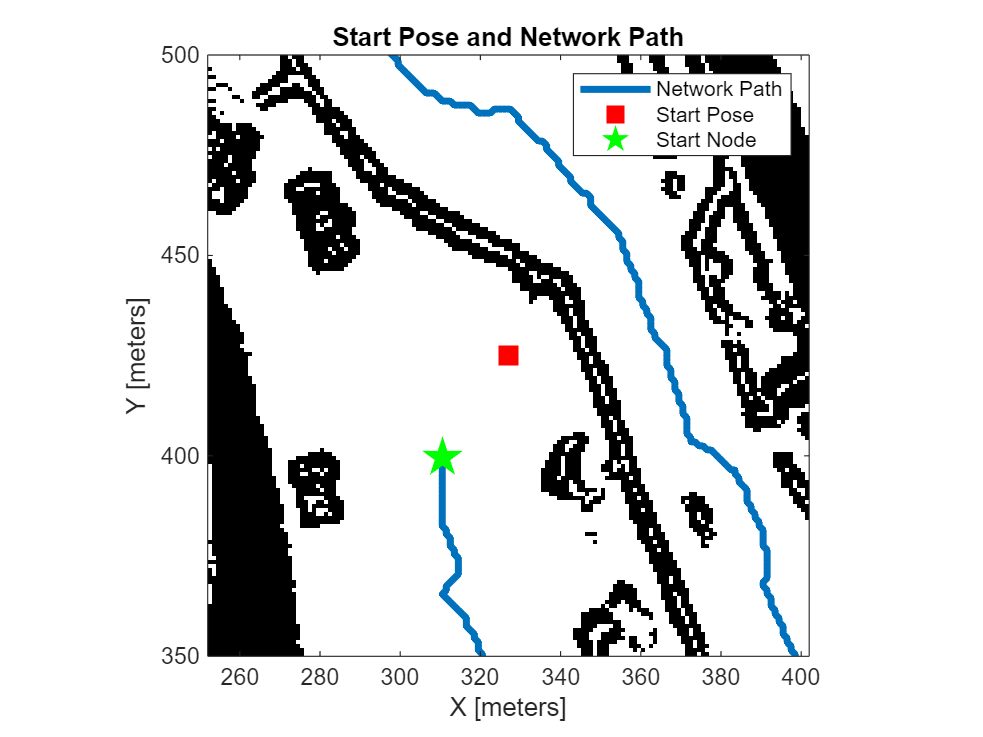

hIm = show(binMap);
hold on
exampleHelperPlotLines(networkPath,{'LineWidth',3});
plot(start(1),start(2),startSpec{:})
plot(smoothedNetworkPath(1,1),smoothedNetworkPath(1,2),goalSpec{:});
axis([start(1)-75 start(1)+75 start(2)-75 start(2)+75])
legend(["Network Path"; "Start Pose"; "Start Node"])
title("Start Pose and Network Path")

Display the edge paths neighboring the start node.

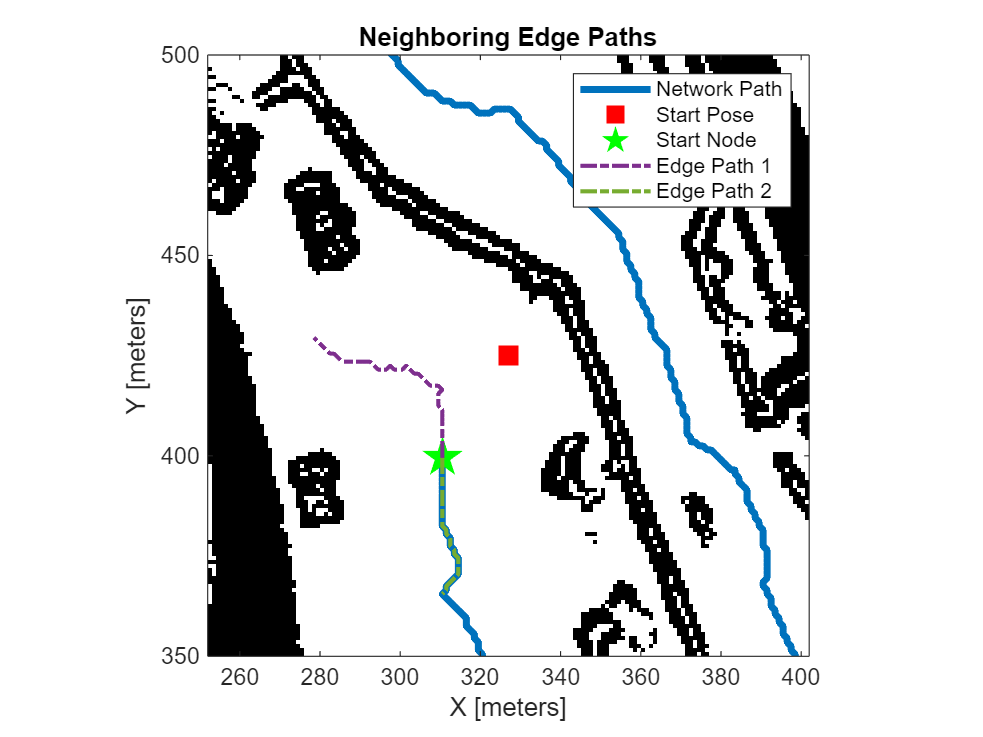

for i = 1:numel(initEdgePaths)
    if ~isequal(initEdgePaths(i).Path(1,:),networkPath(1,:))
        initEdgePaths(i).Path = flipud(initEdgePaths(i).Path);
    end
    exampleHelperPlotLines(initEdgePaths(i).Path,{'-.','LineWidth',1.75});
end
legend(["Network Path"; "Start Pose"; "Start Node"; "Edge Path " + (1:numel(initEdgePaths))'])
title("Neighboring Edge Paths")

Use the `exampleHelperMiningTruckSpecs` helper function to set up the vehicle dimensions and minimum turning radius.

[vehicleLength,vehicleWidth,minTurnRadius] = exampleHelperMiningTruckSpecs;
vehDims = exampleHelperVehicleGeometry(vehicleLength,vehicleWidth,"collisionChecker");

Next, use the [`exampleHelperConnectRSToPath`](matlab:open('exampleHelperConnectRSToPath')) helper function to find the collision-free connection between the starting pose and the network path. This function attempts to create a Reeds-Shepp path segment, using the minimum turning radius of the haul truck, that connects the starting pose either directly to the start node or to the edges neighboring the start node. The function prioritizes connections by proximity, first attempting to connect to the nearest point and, if it cannot connect, moving on to the next closest viable connection point. The process ends as soon as the function finds a collision-free path, or after it exhausts all connection points on the edges neighboring the start node. For more information about Reed-Shepp connections, see the [`reedsSheppConnection`](https://www.mathworks.com/help/nav/ref/reedssheppconnection.html) object.

[onrampPath,onrampIdx] = exampleHelperConnectRSToPath(smoothedNetworkPath,initEdgePaths,start,binMap,vehDims,minTurnRadius);

Append the collision-free onramp path to the start of the smoothed network path.

origStates = [onrampPath; smoothedNetworkPath(onrampIdx:end,:)];

Show the collision-free onramp path. Note that the path starts in reverse because of the starting orientation of the haul truck, and, in this case, it connects to a point at the farthest end of second local grid edge.

exampleHelperPlotLines(onrampPath,{'LineWidth',3});

ans = 1.7530e+03

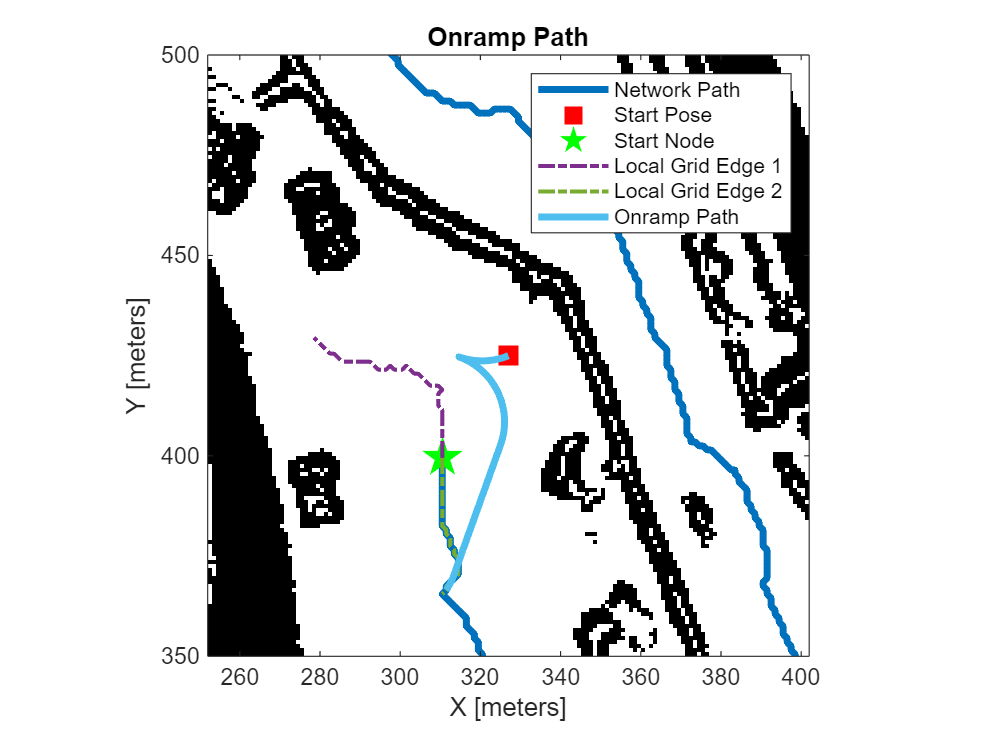

legend(["Network Path"; "Start Pose"; "Start Node"; "Local Grid Edge " + (1:numel(initEdgePaths))'; "Onramp Path"])
title("Onramp Path")
hold off

## Develop Terrain-Aware Planner

In the previous sections, you developed tools for creating and planning on road networks. However, you might encounter scenarios where reaching or exiting a road network is challenging, or the vehicle is located in a region where inferring a road network is not possible. This section shows how to use the `plannerHybridAStar` object as a *terrain-aware* planner by integrating a custom cost function.

### Define Parameters of Vehicle and Global Planner

Use the `exampleHelperTerrainPlannerParams` helper function to define the parameters that represent the geometry and kinematic constraints of the vehicle. The function defines two separate sets of parameters. The first set contains parameters that can change during vehicle operation, such as costs. The second set contains parameters that are likely to remain fixed, such as the length and width of the vehicle.

[tuneableParams,fixedParams] = exampleHelperTerrainPlannerParams;

Convert the digital elevation model, generated in the [Create Route Planner for Offroad Navigation Using Digital Elevation Data](http://./CreateRoutePlannerUsingDigitalElevationData.mlx) example, into a cost map containing terrain gradient and cost information.

[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableParams.MaxAngle,fixedParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

To ensure the global planners have sufficient space to operate, you must create enough clearance around the precalculated road network. To achieve this, convert the road network to an occupancy map, inflate the road network, and then remove those inflated cells from the slope mask. Note that, in practical applications, you can adapt this process to focus instead on eliminating roads that are too narrow for navigation.

Create an empty copy of the terrain occupancy map with the same resolution.

tmpMap = binaryOccupancyMap(zeros(obstacles.GridSize),Resolution=obstacles.Resolution);

Inflate the road network using the geometry of the haul truck.

vehDims = exampleHelperVehicleGeometry(fixedParams.Length,fixedParams.Width,"collisionChecker");
collisionChecker = inflationCollisionChecker(vehDims,fixedParams.NumCircles);
setOccupancy(tmpMap,vertcat(pathList.Path),1,"grid");
inflate(tmpMap,collisionChecker.InflationRadius*1.5);

Show the inflated road network.

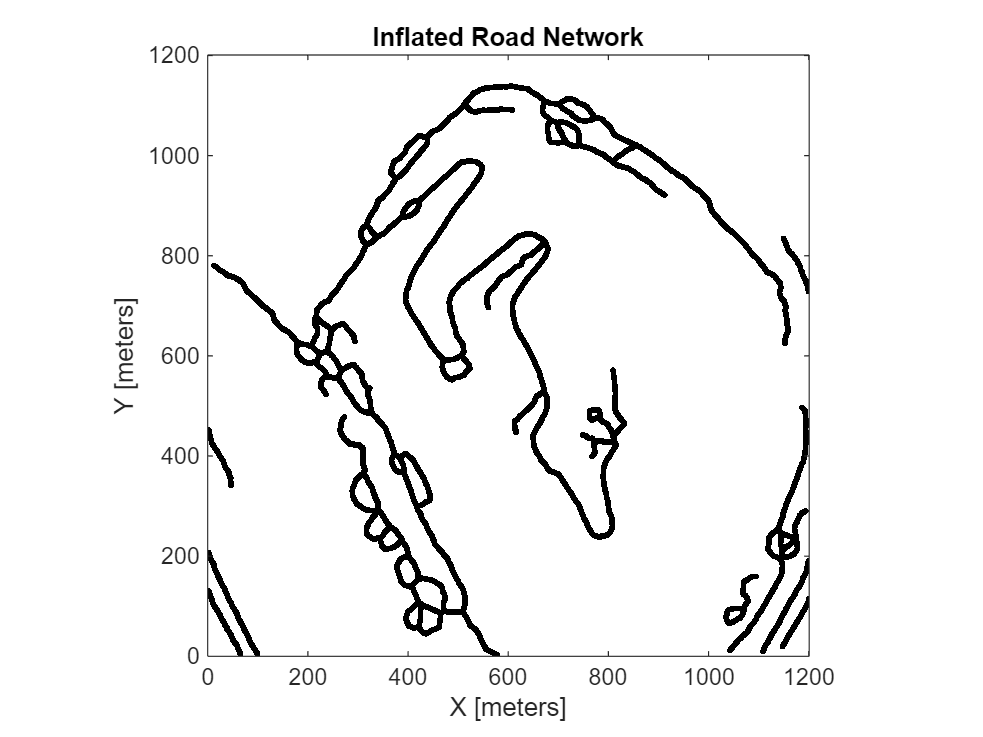

show(tmpMap);
title("Inflated Road Network")

Remove the inflated cells from the original map. Show the widened slope mask.

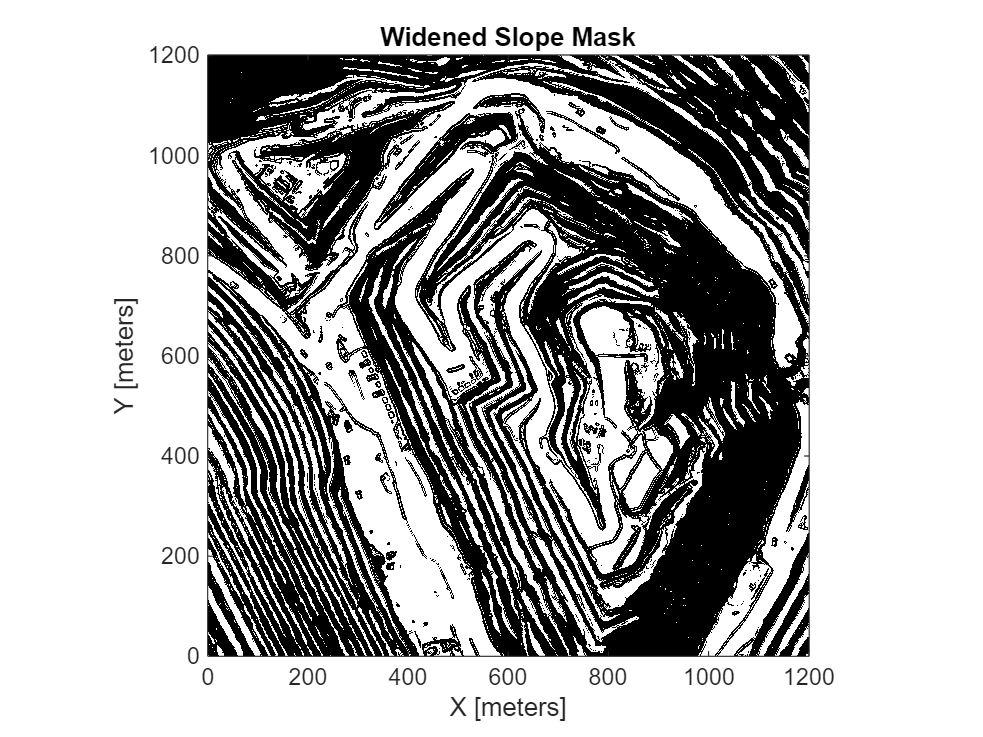

figure
setOccupancy(obstacles,obstacles.occupancyMatrix & ~tmpMap.occupancyMatrix)
show(obstacles);
title("Widened Slope Mask");

### Incorporate Custom Cost Function

Use the [`exampleHelperCreateTerrainPlanner`](matlab:open('exampleHelperCreateTerrainPlanner')) helper function to initialize a `plannerHybridAStar` object with the previously created `costMap` and parameters. 

terrainPlanner = exampleHelperCreateTerrainPlanner(costMap,tuneableParams,fixedParams);

By default, the helper function populates the transition cost function of the planner, stored in the `TransitionCostFcn` property, with the [`exampleHelperZHeuristic`](matlab:open('exampleHelperZHeuristic')) helper function.

This transition function adds the change in terrain height to the distance along the motion primitive. You can use a custom transition function by specifying a function supported by the `TransitionCostFcn` property of a `plannerHybridAStar` object as an additional input to the `exampleHelperCreateTerrainPlanner` function. See the `TransitionCostFcn` property of [`plannerHybridAStar`](https://www.mathworks.com/help/nav/ref/plannerhybridastar.html) for more details.

For more information about incorporating custom costs, see the [Offroad Planning with Digital Elevation Models](https://www.mathworks.com/help/nav/ug/offorad-planning-on-digital-elevation-models.html) example.

### Plan Terrain-Aware Offramp Path

Next, set the end node of the network path as the start node of the terrain-aware problem, and plan a path to the goal pose that lies outside the road network.

start = origStates(end,:); 

Plan a path using the terrain-aware planner.

[terrainAwarePath,motionDir,solnInfo] = plan(terrainPlanner,start,goal);

Save the robot states by concatenating the terrain-aware results to the end of the path.

networkPoses = [networkPath headingFromXY(networkPath)];
originalReferencePath = [onrampPath; networkPoses; terrainAwarePath.States];
smoothedReferencePath = [origStates; terrainAwarePath.States];

### Visualize Offramp Path from Terrain-Aware Planner

Display the terrain-aware planner results.

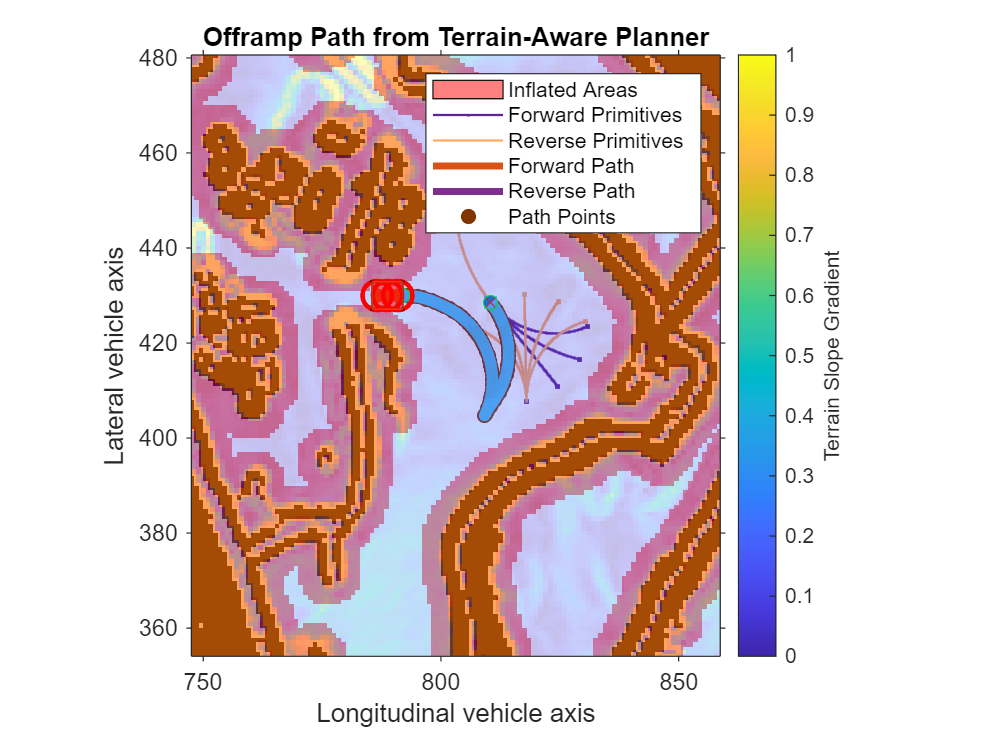

figure
show(terrainPlanner)
hold on
exampleHelperVisualizeTerrainPlanner(terrainAwarePath.States,costMap,fixedParams,tuneableParams)
title("Offramp Path from Terrain-Aware Planner")
legend("Inflated Areas","Forward Primitives","Reverse Primitives","Forward Path","Reverse Path","Path Points")
hold off

Display the map and the offramp path from the end node of the network path to the the goal pose.

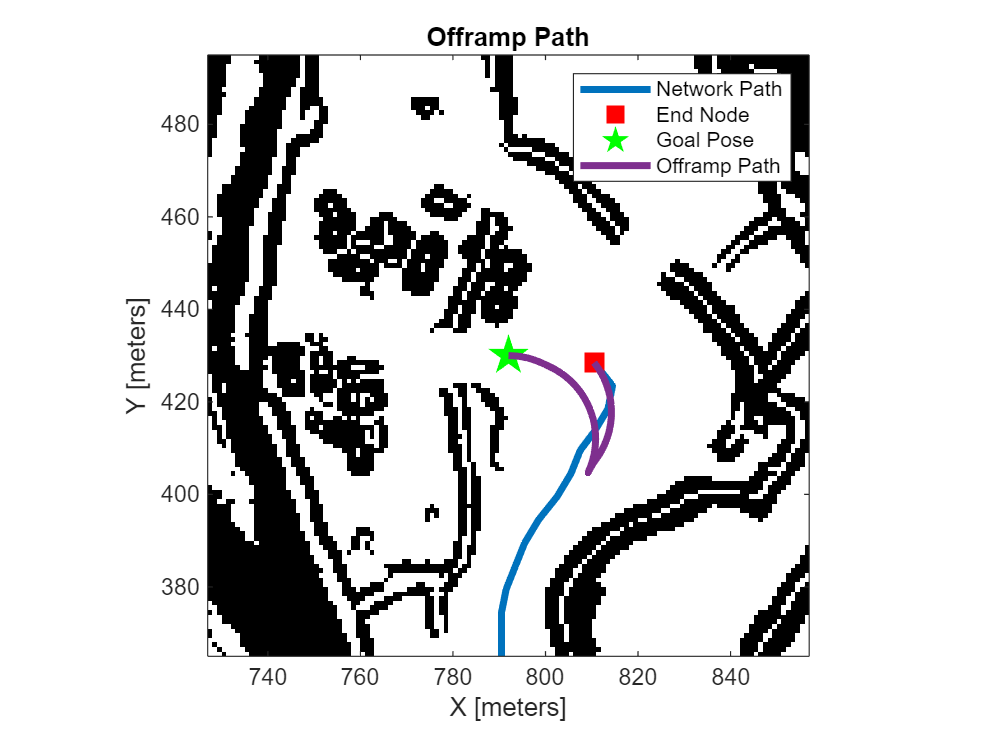

obstacles = getLayer(costMap,"terrainObstacles");
h = show(obstacles);
hold on
exampleHelperPlotLines(smoothedNetworkPath,{'LineWidth',3});
plot(start(1),start(2),startSpec{:})
plot(goal(1),goal(2),goalSpec{:})
exampleHelperPlotLines(terrainAwarePath.States,{'LineWidth',3});
axis([goal(1)-65 goal(1)+65 goal(2)-65 goal(2)+65])
title("Offramp Path")
legend(["Network Path"; "End Node"; "Goal Pose"; "Offramp Path"])

## Conclusion

In this example you developed two different ways of generating collision-free paths while satisfying the kinematic and geometric constraints of a vehicle. 

The first half of the example focused on generating collision-free paths between the SE(2) location of a vehicle and a route found in the road network. You used the [`reedsSheppConnection`](https://www.mathworks.com/help/nav/ref/reedssheppconnection.html) object with the `MinTurningRadius` of the vehicle to generate potential connections to the network, and used a [`validatorVehicleCostmap`](https://www.mathworks.com/help/nav/ref/validatorvehiclecostmap.html) object supplied with the dimensions of the vehicle to check whether those paths were collision-free.

The second half of the example focused on supplying a `plannerHybridAStar` object with a custom cost function that added elevation to the transition cost, biasing the planner toward solutions that minimize vertical motion. This planner also received the same `MinTurningRadius` and `validatorVehicleCostmap`, and can be used in scenarios where the simple onramp planner fails to find a connection or in regions of the map where the road network does not exist.

In the next example, [Navigate Global Path through Offroad Terrain Using Local Planner](matlab:open('./CreateLocalPlannerToNavigateGlobalPath.mlx')), you will use [`controllerTEB`](https://www.mathworks.com/help/nav/ref/controllerteb.html) as a local-planner capable of following the network paths generated in this example, while avoiding obstacles and adhering to the same kinematic and geometric constraints.

*Copyright 2023-2024 The MathWorks, Inc.*